# Reproducing the results of the paper

clear all; close all; clc;
addpath('..\')

Load the dataset 

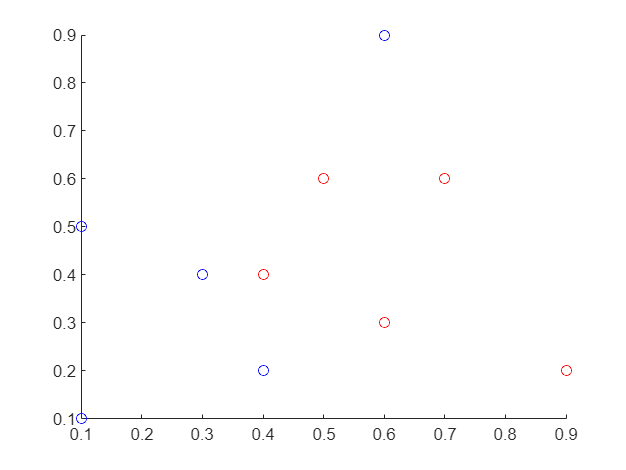

x1 = [0.1,0.3,0.1,0.6,0.4];
y1 = [0.1,0.4,0.5,0.9,0.2];

x2 = [0.6,0.5,0.9,0.4,0.7];
y2 = [0.3,0.6,0.2,0.4,0.6];

scatter(x1, y1, 'blue')
hold on;
scatter(x2, y2, 'red')


x = [x1, x2; y1, y2];
y = [ones(1,5) zeros(1,5); zeros(1,5) ones(1,5)];

Define the hyperparameters of the network:

- `shape`     contains the number of neuron per layer of the network

- `sigma` and `sigmaprime`     are the activation function of the network, here we use sigmoid

- `niter`     is the maximum number of iterations

- `eta`         is the learning rate

sigma = @(t) 1./(1+exp(-t));
sigmaprime = @(t) sigma(t).*(1-sigma(t));
shape = [2, 3, 3, 2];
niter = 8e4;
eta = 0.05;

### Training

[costHistory, W, b] = GradientDescent( ...
        x, y, niter, sigma, sigmaprime, eta, shape);

10.0%
20.0%
30.0%
40.0%
50.0%
60.0%
70.0%
80.0%
90.0%
100.0%


Plot the evolution of the cost function against the iterations.

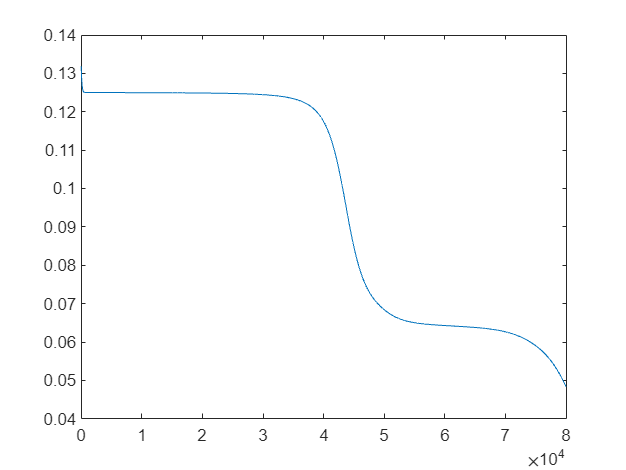

figure
plot(linspace(0,niter,niter)', costHistory, '-')

fprintf('Cost Function: %f\n', costHistory(end));

Cost Function: 0.048319


### Prediction

Generate some other data in the domain to test the performance of the network.

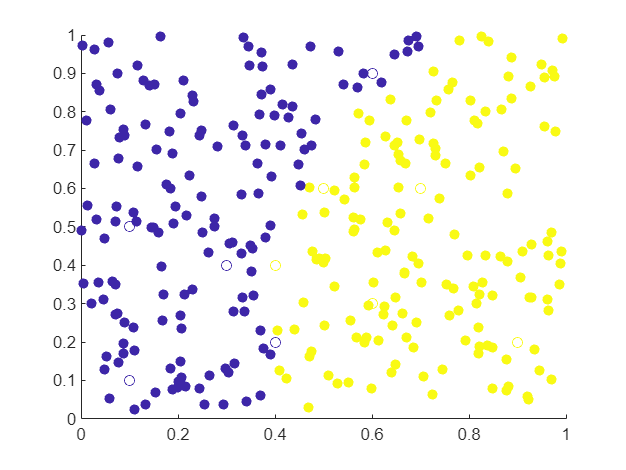

% generate new random data in the square [0,1]^2
n = 300;
testDatax = rand(n, 2);
testDatay = PredictClasses(W, b, sigma, testDatax');

x = x';
y = int32([zeros(5, 1); ones(5, 1)]');
figure
scatter(x(:,1), x(:,2), [], y, 'o');
hold on;
scatter(testDatax(:,1), testDatax(:,2), [], testDatay, 'filled');

# Testing our implementation in a more involved case

Here we use a synthetic dataset that has been generated using the python script reported in the repository. The dataset contains points in R^2 clustered in 4 different classes.

### Pre-processing

clear all; clc;

Load the dataset and set its parameters

load X.mat; load y.mat; y = Y;

n = size(X, 1);
d = size(X, 2);
n_classes = 4;

Visualize the dataset

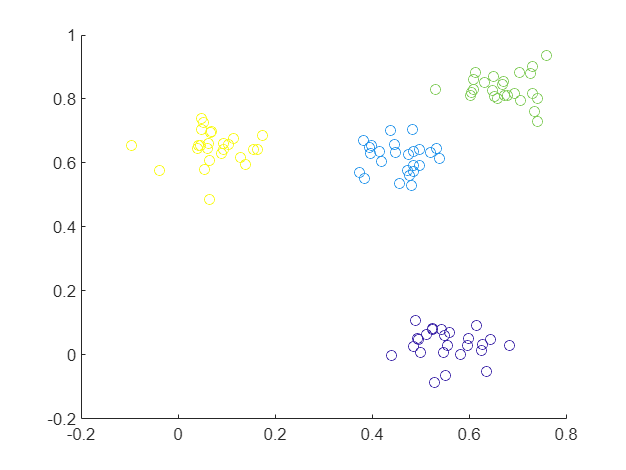

figure
scatter(X(:, 1), X(:, 2), [], y);


% transform y to categorical
y_cat = zeros(4, n);
for k = 1:n
    y_cat(y(k)+1,k) = 1;
end

Split the dataset into training and test 

split_ratio = 0.3;
k = floor(split_ratio*n);

X_train = X(1:k,:);
X_test = X(k+1:end,:);
y_train = y(1:k);
y_test = y(k+1:end);
y_train_cat = y_cat(:,1:k);
y_test_cat = y_cat(:,k+1:end);

Define some hyperparameters of the network

sigma = @(t) 1./(1+exp(-t));
sigmaprime = @(t) sigma(t).*(1-sigma(t));

shape = [d, 2, 2, n_classes];

niter = 3e5;
eta = 0.05;

### Training

[costHistory, W, b] = GradientDescent( ...
        X_train', y_train_cat, niter, sigma, sigmaprime, eta, shape);

10.0%
20.0%
30.0%
40.0%
50.0%
60.0%
70.0%
80.0%
90.0%
100.0%


% save NNparams.mat W b costHistory
% load NNparams.mat

Plot `costHistory` as done before

figure
plot(linspace(0,niter,niter)', costHistory, '-')
fprintf('Cost Function: %f\n', costHistory(end));

Cost Function: 0.002967


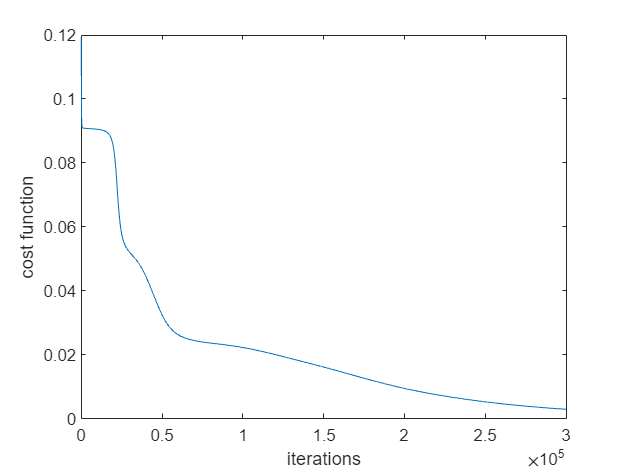

xlabel('iterations')
ylabel('cost function')

### Test

Predict the class of the points in the test set using the network

y_pred = PredictClasses(W, b, sigma, X_test');

Plot the prediction

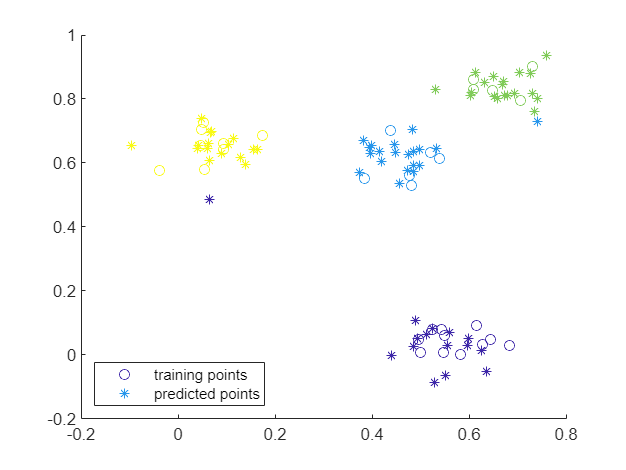

figure
scatter(X_train(:, 1), X_train(:, 2), [], y_train, 'o');
hold on;
scatter(X_test(:, 1), X_test(:, 2), [], y_pred, '*');
legend('training points', 'predicted points', 'Location','southwest')

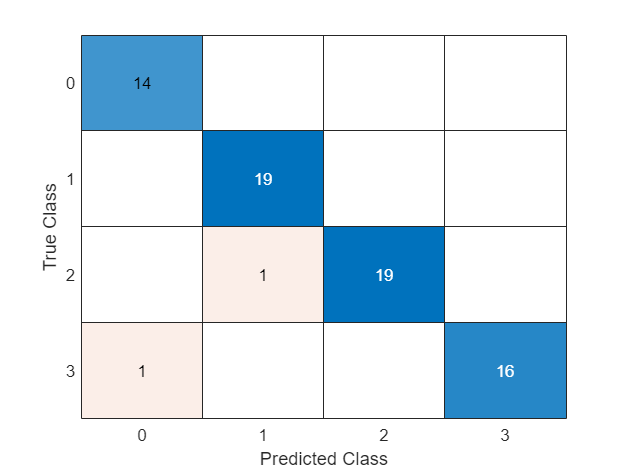

% confusion matrix
figure
y_test = int32(y_test);
confusionchart(y_test,y_pred)

### Boundary exploration

We'd like to understand the criterion the network has learned to categorize the points. Therefore we generate a set of points that is suppose to fill the whole domain, and see how the network classifies the latter.

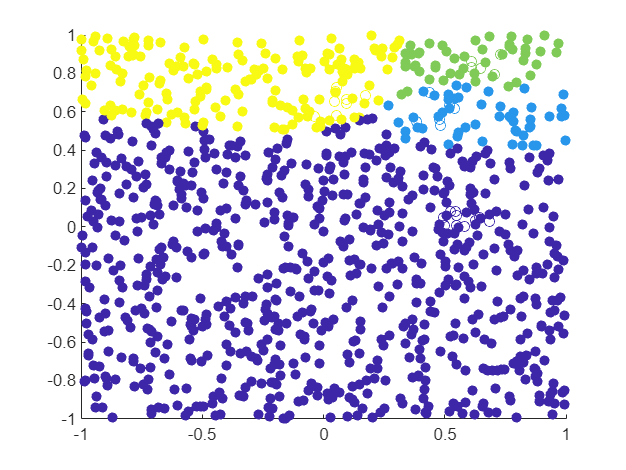

% generate new random data in the square [0,1]^2
n = 1000;
testDatax = -1 + 2*rand(n, 2);
testDatay = PredictClasses(W, b, sigma, testDatax');

figure
scatter(X_train(:,1), X_train(:,2), [], y_train, 'o');
hold on;
scatter(testDatax(:,1), testDatax(:,2), [], testDatay, 'filled');